## [Classification with Machine Learning](https://apmonitor.com/pds/index.php/Main/ClassificationOverview)

Classification is the problem of identifying which set of categories based on observation features. The decision is based on a training set of data containing observations where category membership is known (supervised learning) or where category membership is unknown (unsupervised learning).

A basic example is to determine the number from pixelated images in a built-in sklearn dataset. The script predicts 0-9 from the following images with a Support Vector Classifier.

Generating data

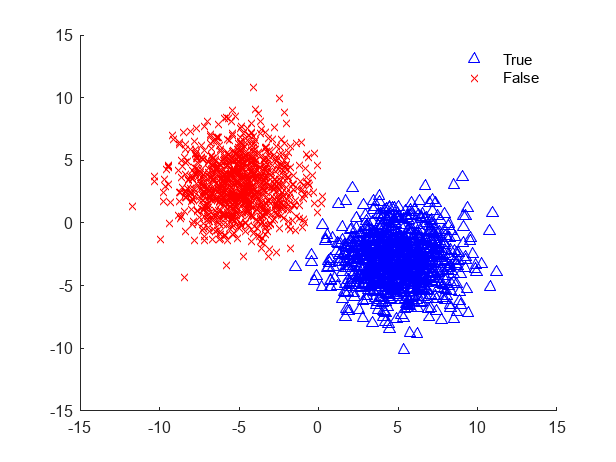

select_option = 6;

data_options = {'linear','quadratic','target','moons','circles','blobs'};
option = data_options{select_option};
n = 2000; % number of data points

X = rand(n,2);
mixing = 0.0; % add random mixing element to data
xplot = linspace(0,1,100);

if strcmp(option,'linear')
    y = false(n,1);
    for i=1:n
        if (X(i,1)+X(i,2))>=(1.0+mixing/2-rand(1)*mixing)
            y(i)=false;
        else
            y(i)=true;
        end
    end
    yplot=1-xplot;

elseif strcmp(option,'quadratic')
    % Initialize y and yplot
    y = false(1, n);
    
    % Compute y based on X values
    for i = 1:n
        if X(i,1)^2 >= X(i,2) + (rand()-0.5)*mixing
            y(i) = false;
        else
            y(i) = true;
        end
    end
    yplot = xplot.^2;

elseif strcmp(option,'target')   
    % Initialize y and yplot
    y = false(1, n);
    j = false;
    yplot = NaN(1, 100);
    
    % Compute y based on X values
    for i = 1:n
        if (X(i,1)-0.5)^2 + (X(i,2)-0.5)^2 <= 0.1 + (rand()-0.5)*0.2*mixing
            y(i) = false;
        else
            y(i) = true;
        end
    end
    
    % Compute yplot based on xplot values
    for i = 1:numel(xplot)
        r = 0.1 - (xplot(i)-0.5)^2;
        if r <= 0
            yplot(i) = NaN;
        else
            j = ~j; % plot both sides of circle
            yplot(i) = (2*j-1)*sqrt(r)+0.5;
        end
    end


elseif strcmp(option,'moons')
    [X,y] = twomoons(n);
    yplot = zeros(size(xplot));
elseif strcmp(option,'circles')
    [X,idx] = twocircles(n);
    yplot = zeros(size(xplot));
elseif strcmp(option,'blobs')
    [X, y] = makeblobs(n,[5 -3; -5 3],2.0);
    yplot = zeros(size(xplot));
end    

% Plot the data

if ~ismember(option,{'circles'})
    figure;
    hold on;
    scatter(X(y > 0.5, 1), X(y > 0.5, 2), 'b', '^', 'DisplayName', 'True');
    scatter(X(y < 0.5, 1), X(y < 0.5, 2), 'r', 'x', 'DisplayName', 'False');
    if ~ismember(option, {'moons', 'blobs'})
        plot(xplot, yplot, 'k.', 'DisplayName', 'Division');
    end
else
    figure;
    hold on;
    gscatter(X(:,1),X(:,2),idx);
end
legend('show');



[trainInd,valInd,testInd] = dividerand(n,0.5,0,0.5);
XA = X(trainInd,:);
XB = X(testInd,:);
yA = y(trainInd,:);
yB = y(testInd,:);


The function "twomoons" below is to generate moon-shaped data

[https://www.mathworks.com/help/stats/label-data-using-semi-supervised-learning-techniques.html](https://www.mathworks.com/help/stats/label-data-using-semi-supervised-learning-techniques.html)

function [X,label] = twomoons(n) % Generate two moons, with n points in each moon.
% Specify the radius and relevant angles for the two moons.
noise = (1/6).*randn(n,1);
radius = 1 + noise;
angle1 = pi + pi/10;
angle2 = pi/10;

% Create the bottom moon with a center at (1,0).
bottomTheta = linspace(-angle1,angle2,n)';
bottomX1 = radius.*cos(bottomTheta) + 1;
bottomX2 = radius.*sin(bottomTheta);

% Create the top moon with a center at (0,0).
topTheta = linspace(angle1,-angle2,n)';
topX1 = radius.*cos(topTheta);
topX2 = radius.*sin(topTheta);

% Return the moon points and their labels.
X = [bottomX1 bottomX2; topX1 topX2];
label = [ones(n,1); zeros(n,1)];
end

The function "twocircle" below is to generate moon-shaped data

function [X,idx] = twocircles(n) % Generate two moons, with n points in each moon.
% Specify the radius and relevant angles for the two moons.
r1 = 3;   % Radius of first circle
r2 = 6;   % Radius of second circle
theta = linspace(0,2*pi,n)';

X1 = r1*[cos(theta),sin(theta)]+ rand(n,1); 
X2 = r2*[cos(theta),sin(theta)]+ rand(n,1);
X = [X1;X2]; % Noisy 2-D circular data set
idx = spectralcluster(X,2);
end


The function "makeblob" below is to generate blobbed data

function [X,y] = makeblobs(n,centers,cluster_std) % Generate two moons, with n points in each moon.
y = zeros(n, 1);
c1 = centers(1,:);
c2 = centers(2,:);


for i = 1:size(centers, 1)
    X((i-1)*n/size(centers, 1)+1:i*n/size(centers, 1), :) = bsxfun(@plus, cluster_std*randn(n/size(centers, 1), 2), centers(i,:));
    
    % Calculate the distance of each point to each cluster center
    d1 = sqrt(sum(bsxfun(@minus, X, c1).^2, 2));
    d2 = sqrt(sum(bsxfun(@minus, X, c2).^2, 2));
    % Assign labels based on distance to the nearest cluster
    y(d1 < d2) = true;
    y(d1 >= d2) = false;
end
end